# Rigid Body Kinematics MATLAB Problem

Solve the velocity of point A for any angle theta. Plot the velocity versus theta function from 0 to 2pi. The angular velocity of the disk is a constant 2 rad/sec. Plot the points on the velocity figure where the velocity of point A is zero.

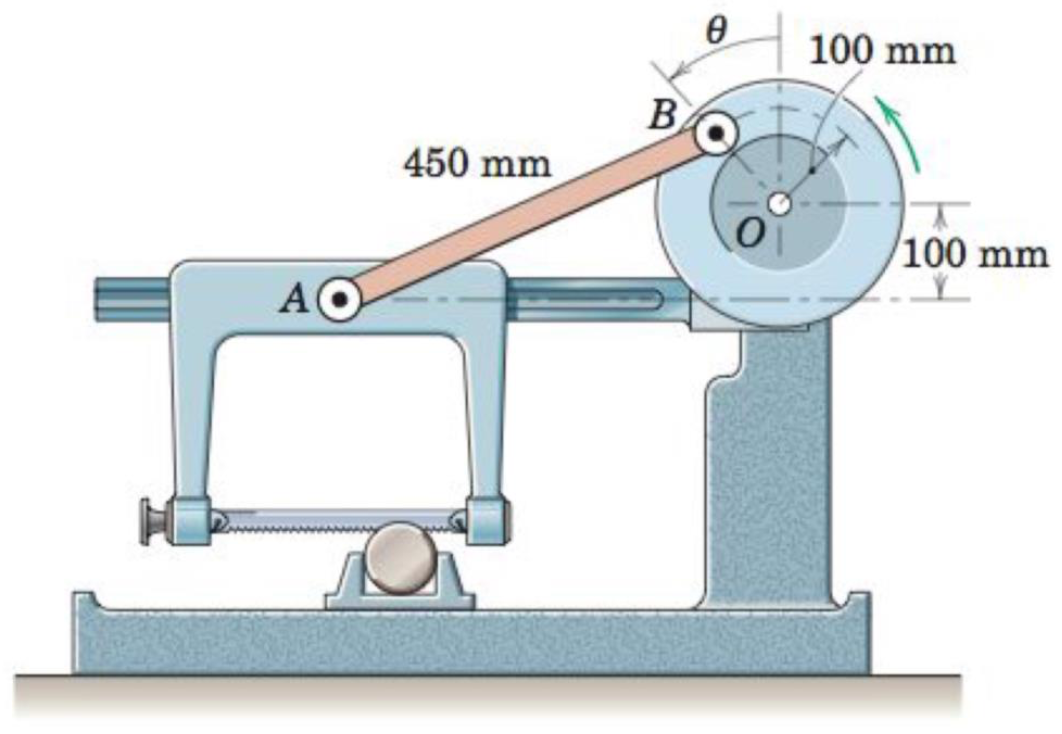

## Find Expressions of v_A and phi_dot

clc
clf
clear
syms L theta theta_dot phi phi_dot v_A r

v_B = [0;0;0]+cross([0;0;theta_dot],r*[-sin(theta);cos(theta);0]) == ...
    v_A*[1;0;0]+cross([0;0;phi_dot],L*[cos(phi);sin(phi);0]) 

$$v\_B = \left(\begin{array}{c} -r\,\dot{\theta }\,\cos\left(\theta \right)=v_{A}-L\,\dot{\varphi }\,\sin\left(\varphi \right)\\ -r\,\dot{\theta }\,\sin\left(\theta \right)=L\,\dot{\varphi }\,\cos\left(\varphi \right)\\ 0=0 \end{array}\right)$$

unknowns = solve(v_B,v_A,phi_dot);
v_A = unknowns.v_A

$$v\_A = -\frac{r\,\dot{\theta }\,\left(\cos\left(\varphi \right)\,\cos\left(\theta \right)+\sin\left(\varphi \right)\,\sin\left(\theta \right)\right)}{\cos\left(\varphi \right)}$$

phi_dot = unknowns.phi_dot

$$phi\_dot = -\frac{r\,\dot{\theta }\,\sin\left(\theta \right)}{L\,\cos\left(\varphi \right)}$$

eqn = L*int(cos(phi),phi,asin(200/450),phi) == -r*int(sin(theta),theta,0,theta)

$$eqn = -L\,\left(\sin\left(\frac{1037075392659999}{2251799813685248}\right)-\sin\left(\varphi \right)\right)=r\,\left(\cos\left(\theta \right)-1\right)$$

syms cp
sinphi = solve(subs(eqn,str2sym('sin(phi)'),cp),cp)

$$sinphi = \frac{r\,\left(\cos\left(\theta \right)-1\right)+L\,\sin\left(\frac{1037075392659999}{2251799813685248}\right)}{L}$$

cosphi = sqrt(1+sinphi^2);
vP1 = simplify(subs(unknowns.v_A,[str2sym('cos(phi)'),str2sym('sin(phi)')],[cosphi,sinphi]));
phidot1 = simplify(subs(unknowns.phi_dot,str2sym('cos(phi)'),cosphi));

## Plot Velocity & Points

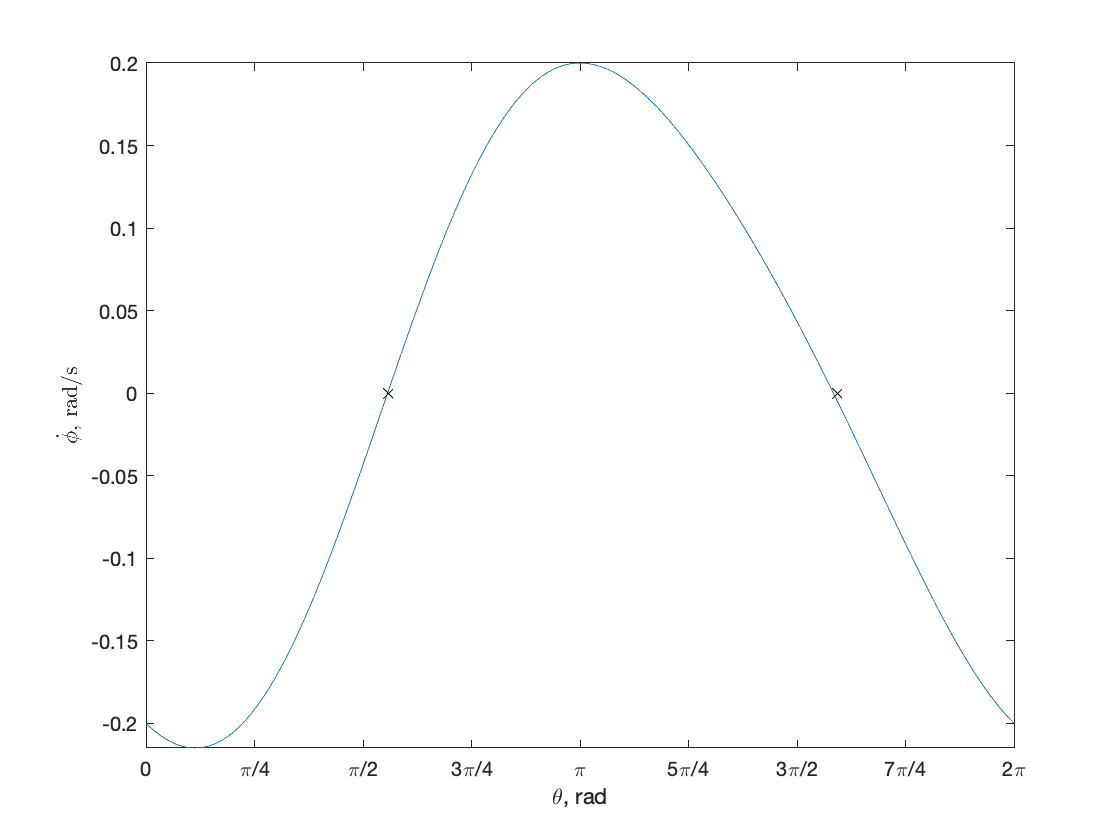

vPplot = subs(vP1,[r,L,theta_dot],[0.1,0.45,2]);
phidotplot = subs(phidot1,[r,L,theta_dot],[0.1,0.45,2]);
fplot(vPplot,[0,2*pi],'MeshDensity',360)
xlabel('\theta, rad')
ylabel('v_A, m/s')
set(gca,'XTick',0:pi/4:2*pi,'XTickLabel',...
    [{"0"},{"\pi/4"},{"\pi/2"},{"3\pi/4"},{"\pi"},{"5\pi/4"},{"3\pi/2"},{"7\pi/4"},{"2\pi"}])

hold on
plot([1.7536,5.0021],[0,0],'xk')
xlabel('\theta, rad')
ylabel('$$\dot{\phi}$$, rad/s','Interpreter','latex')
set(gca,'XTick',0:pi/4:2*pi,'XTickLabel',...
    [{"0"},{"\pi/4"},{"\pi/2"},{"3\pi/4"},{"\pi"},{"5\pi/4"},{"3\pi/2"},{"7\pi/4"},{"2\pi"}])

## Angles of Theta Where v_A = 0

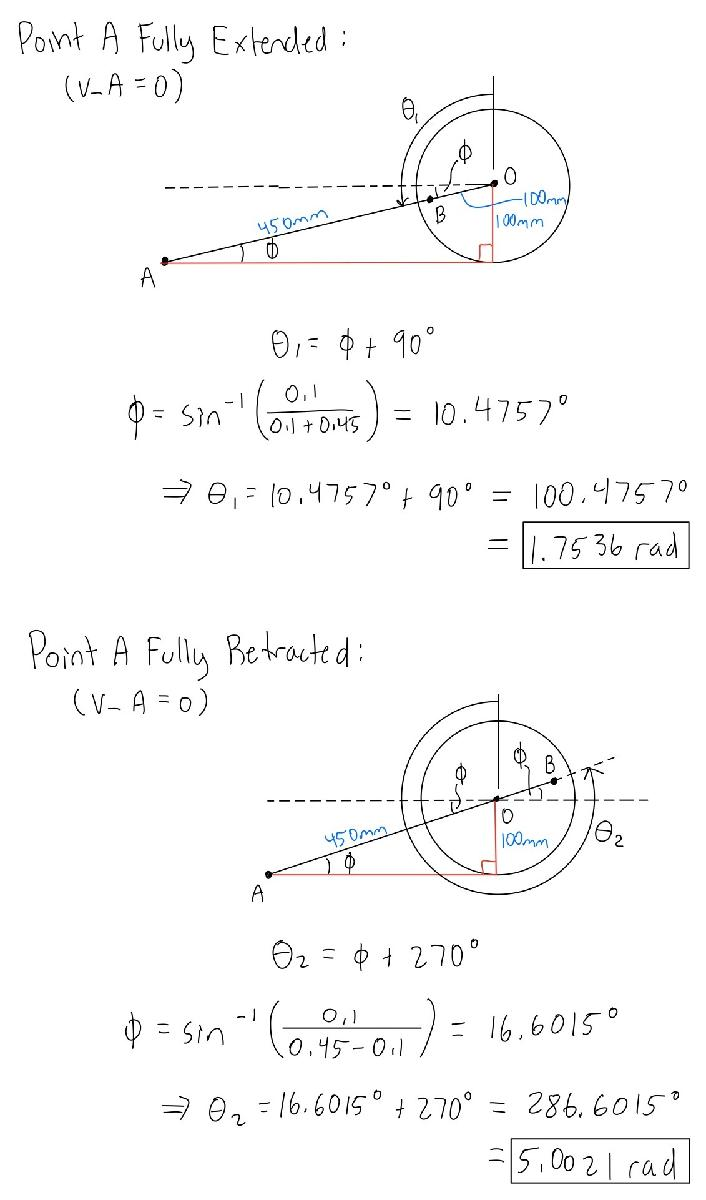

## Physical Significance

These two angles represent the points (1.7536,0) and (5.0021,0) on the graph above. The physical significance of these two points is that this is where the velocity of point A is zero. When the angle theta is 1.7536 rad, point A is fully extended along the slider. Similarly, when the angle theta is 5.0021 rad, point A is fully retracted along the slider in reference to the disk. Since these points represent the limits of the motion of point A, the linear velocity must be zero. The motion of point A is similar to that of a spring-mass system. When the mass is at its maximum displacement, the velocity of the mass is zero.

The velocity of point A is positive when theta is between 1.7536 rad and 5.0021 rad. When theta ranges from 5.0021 rad to 1.7536 rad, the velocity of point A is negitive. In other words, when point B is rounding the lower part of the disk, point A will be moving to the right. And when point B is rounding the upper part of the disk with a positive angular velocity, point A moves to the left in the x direction.

## Contribution Summary

Jacob: code devepopment, diagrams, analytical solution for zero velocity points, point A velocity analytical solution

Dennis: code devepopment, diagrams, analytical solution for zero velocity points, point A velocity analytical solution

Christopher: code devepopment, diagrams, analytical solution for zero velocity points, point A velocity analytical solution

Each team member had a contribution to every part of the project. We decided to focus on single tasks along the course of the project and work through them as a team. For example, during code development, we all were involved in this process and checked each other's work. Towards the end of the project, we all combined each others work in to a single file until reaching the final result.